clear

addpath('matlab_functions\')

N = 100;
M = 10;

g = gausswin(floor(N/M)*2);

Phi = sparse(N,M);
for j = 1:M
    a = N / (2*M) * (2*j-1) - length(g) / 2;
    a = floor(a);
    b = a + length(g) - 1;
    if a < 1
        Phi(1:b, j) = g(-a+2:end);
    elseif b > N
        Phi(a:N, j) = g(1:end+N-b);
    else
        Phi(a:b, j) = g;
    end
end
clear a b j g
Phi = full(Phi');

x = zeros(N,1);
x(10:15) = 1;
x(50:57) = 1;
x(70:72) = 1;

y = Phi * x + randn(M,1) * 0;

tic
x2 = BBL(Phi, y);
toc

Elapsed time is 0.148411 seconds.


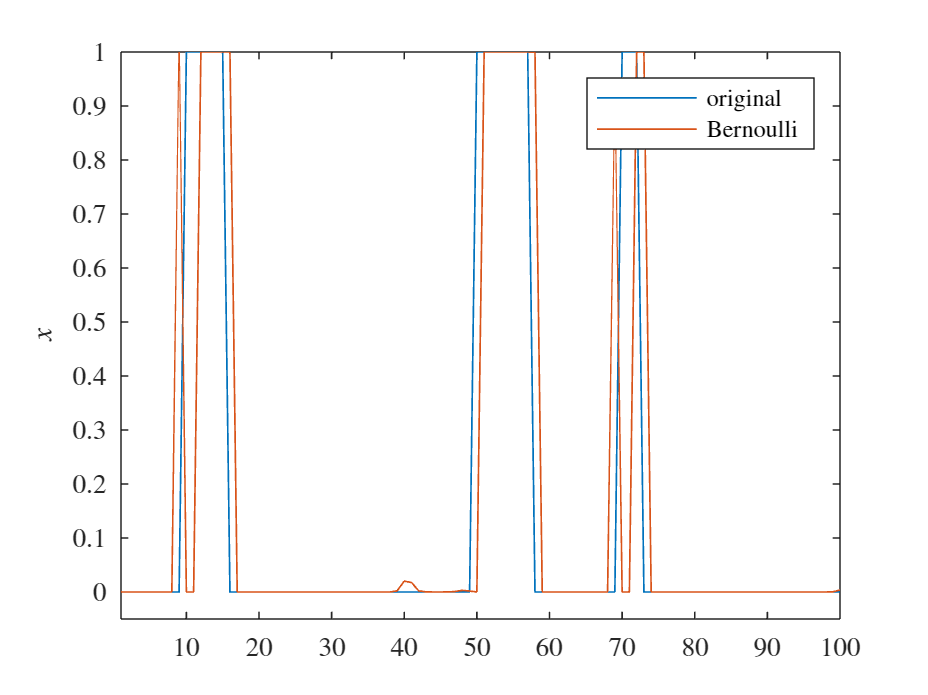


figure
hold on
plot(x,  'DisplayName','original')
plot(x2, 'DisplayName','Bernoulli')
legend('Interpreter','latex')
xlim([1 N])
ylim([-0.05 inf])
ylabel('$x$', 'Interpreter','latex')
box on

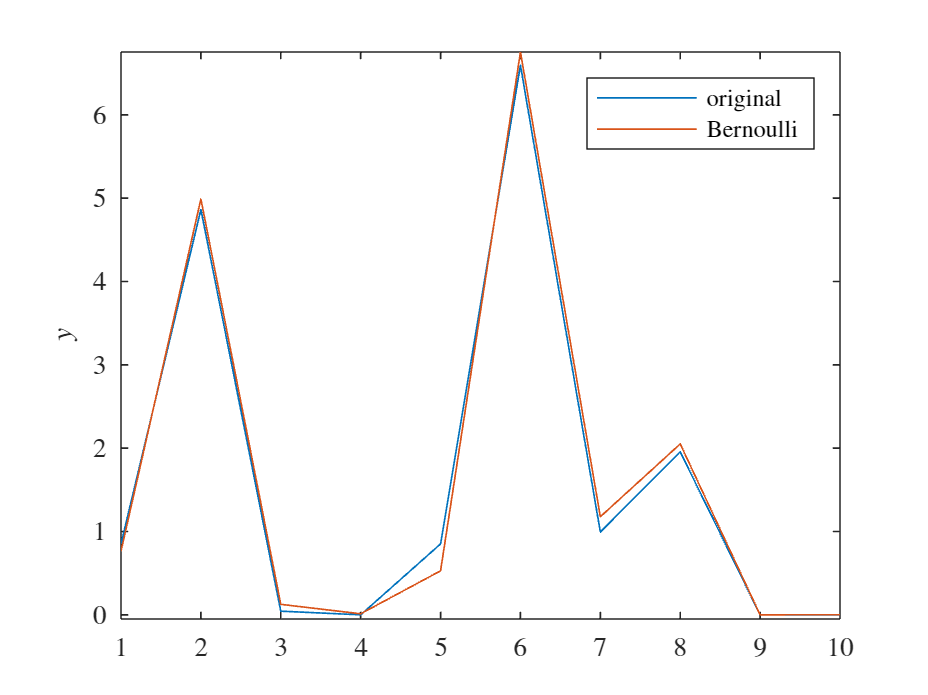


figure
hold on
plot(y,        'DisplayName','original')
plot(Phi * x2, 'DisplayName','Bernoulli')
legend('Interpreter','latex')
ylim([-0.05 inf])
xlim([1 M])
ylabel('$y$', 'Interpreter','latex')
box on